clear
clc

Problema1 d)

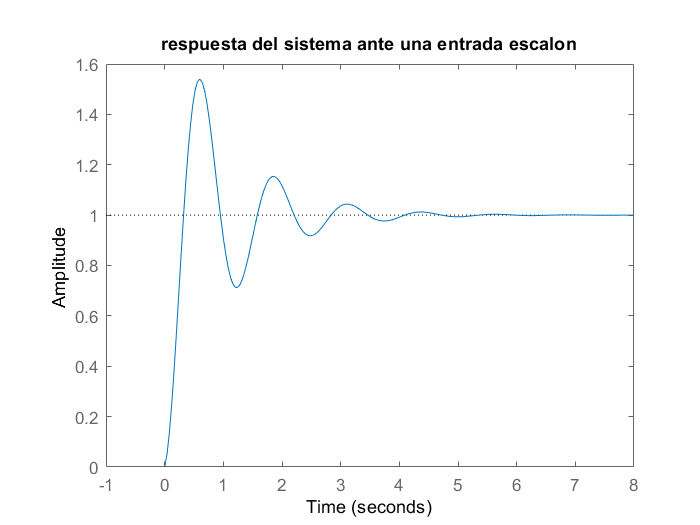

figure(1)
sys1d = tf([0.8 26],[1 2 26]);
t = -1:0.04:8;
step(sys1d,t)
title('respuesta del sistema ante una entrada escalon')

Problema 2 

num_G1=[6.1988 9.9265 82.6865 78.9594];
den_G1=[1 6.6459 25.3141 100.6424 110.2788 78.9594];

los cero de $G_1$

roots([6.1988 9.9265 82.6865 78.9594])

ans =   -0.3007 + 3.5563i
  -0.3007 - 3.5563i
  -1.0000 + 0.0000i


las raices del polinomio $G_1$, osea los polos son:

roots([1 6.6459 25.3141 100.6424 110.2788 78.9594])

ans =   -4.8758 + 0.0000i
  -0.2585 + 3.8582i
  -0.2585 - 3.8582i
  -0.6265 + 0.8310i
  -0.6265 - 0.8310i


num_G2=12.5771;
dem_G2=[1 6.0676 13.4429 12.5771];

$G_2$ no tiene ceros 

las raices del polinomio $G_2$, osea los polos son:

roots([1 6.0676 13.4429 12.5771])

ans =   -2.9636 + 0.0000i
  -1.5520 + 1.3547i
  -1.5520 - 1.3547i


si los polos son positivo, osea estan en el semiplano derecho el sistema sería inestable.

Problema 3

syms s ;
P =(s^2+7)*(s+1);

el polinomio caracteristico expandido  

T= expand (P)

$$T = s^{3}+s^{2}+7\,s+7$$


 num= 40;
 den= [ 1 1 7 7];

 las matrices del sistema son 

[A,B,C,D] = tf2ss(num,den)

A =     -1    -7    -7
     1     0     0
     0     1     0


B =      1
     0
     0


C =      0     0    40


D = 0

Problema 4 

el polinomio caracteristico es 

Pol= s^2+2*s+10

$$Pol = s^{2}+2\,s+10$$

$2\xi \omega_n$=2

$\omega_n$=$\sqrt{10}$

entonces $\xi =\frac{1}{\sqrt{10}}$

La funcion del sobre paso es:


$$\textrm{Sp}=\exp \left(\frac{-\xi \pi }{\sqrt{1-\xi^2 }}\right)$$


evaluando $\xi$ queda 

 chi=1/10^(1/2);
Sp= exp(-chi*pi/(1-(chi)^2)^(1/2))

Sp = 0.3509

La funcion del tiempo de levantamiento es:


$$t_p =\frac{\pi }{\omega_n \sqrt{1-\xi^2 }}$$


evaluando 

wn=10^(1/2);
tp=pi/wn*((1-(chi)^2)^(1/2))

tp = 0.9425

La funcion para la banda de asentamiento :

$\delta =$$\exp \left(\xi \omega_n t_s \right)$/$\sqrt{1-\xi^2 }$

%delta= exp(chi*wn*ts)/(1-(chi)^2)^(1/2)

La funcion para el tiempo de asentamiento es:


$$t_s =\ln \left(\frac{1}{\delta *\sqrt{1-\xi^2 }}\right)*\frac{1}{\xi \omega_n }$$


De las especificaciones se tiene:

syms Chi
solve(0.2== exp((-Chi*pi)/sqrt((1-(Chi)^2))), Chi, 'Real', true)

$$ans = \frac{\log\left(5\right)}{\sqrt{\pi^{2}+{\log\left(5\right)}^{2}}}$$

entonces $\xi$ para la especificacion es:

xhi=log(5)/(pi^2 + log(5)^2)^(1/2)

xhi = 0.4559

para el tiempo de levantamiento, si $t_p =4\textrm{seg}$

%% 
syms W_n
solve(4== (pi/W_n*((1-(xhi)^2)^(1/2))), W_n, 'Real', true);
Wn=(8016456775260029*pi)/36028797018963968

Wn = 0.6990


tetha=acosd(xhi);
%xwn=-xhi*Wn;

el polinomio de las especificaciones es  $s^2 +0\ldotp 6374s+0\ldotp 4886$


%pol_e=s^2+2*xhi*Wn*s+Wn^2

las raices del polinomio de las especificaciones son :

figure (2)
roots([1 2*xhi*Wn Wn^2])

ans =   -0.3187 + 0.6221i
  -0.3187 - 0.6221i


% -0.3187 + 0.6221i
% -0.3187 - 0.6221i
x=-0.3187;
y=+0.6221;
x1=-0.3187;
y1=-0.6221;
figure(2)
plot (x,y, 'b:d')
hold on
plot (x1,y1,'b:d')
grid on 
title('plano s de las especificaciones')
ylabel ('eje imaginario');
xlabel('eje real');



las raices del polinomio $s^2 +2s+10$ son

roots([1 2 10])

ans =   -1.0000 + 3.0000i
  -1.0000 - 3.0000i


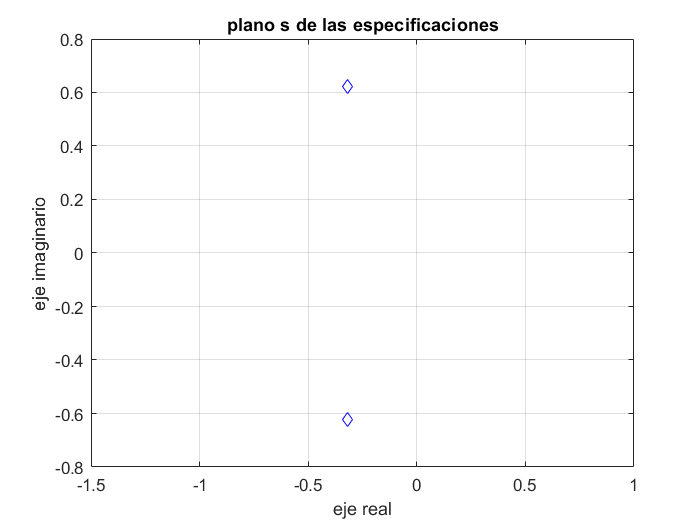

hold off

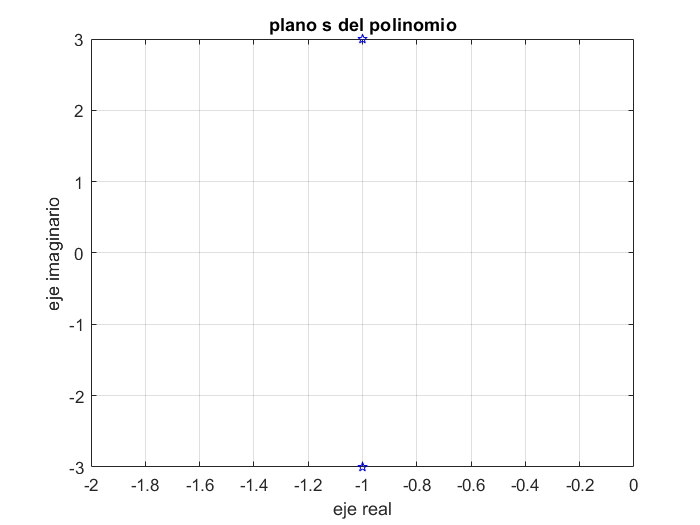


x2=-1.0000; 
y2= 3.0000;
x3=-1.0000; 
y3=- 3.0000;

figure (3)
plot (x2,y2, 'b:p')
hold on
plot (x3,y3,'b:p')
grid on 
title('plano s del polinomio')
ylabel ('eje imaginario');
xlabel('eje real');
hold off

el sistema no cumple con las especificaciones entregadas, ya que, las raices del polinomio y las de las especificaciones no son las misma.